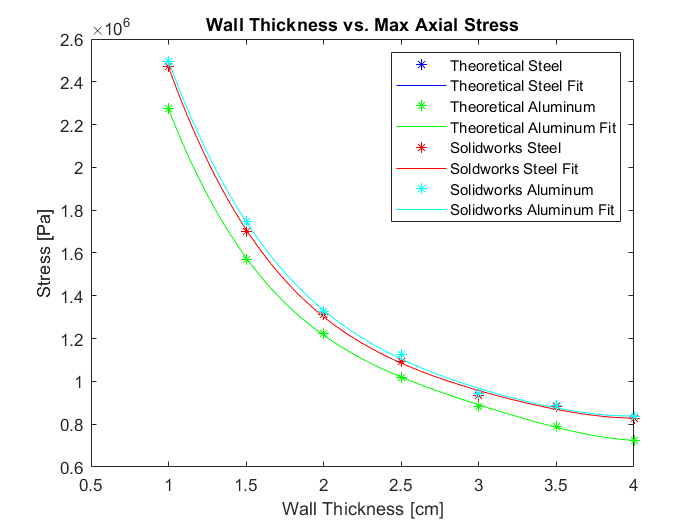

 %for wall thickness and max axial stress theoretical steel
    pt1 = [1 stress1];
    pt2 = [1.5 stress2];
    pt3 = [2 stress3];
    pt4 = [2.5 stress4];
    pt5 = [3 stress5];
    pt6 = [3.5 stress6];
    pt7 = [4 stress7];
    
    % Pick the parameter values
    t1 = 0;
    t2 = 1/6;
    t3 = 2/6;
    t4 = 3/6;
    t5 = 4/6;
    t6 = 5/6;
    t7 = 1;
    % Find the A matrix
    A = [1 t1 t1^2 t1^3 t1^4;...
         1 t2 t2^2 t2^3 t2^4;...
         1 t3 t3^2 t3^3 t3^4;...
         1 t4 t4^2 t4^3 t4^4;...
         1 t5 t5^2 t5^3 t5^4;...
         1 t6 t6^2 t6^3 t6^4;...
         1 t7 t7^2 t7^3 t7^4];
    % find the right hand side for x and y 
    xRHS = [pt1(1);pt2(1);pt3(1);pt4(1);pt5(1);pt6(1);pt7(1)];
    yRHS = [pt1(2);pt2(2);pt3(2);pt4(2);pt5(2);pt6(2);pt7(2)];
    % Solve for coefficients
    a = A\xRHS;
    b = A\yRHS;
    t = 0:0.01:1; % values for parameter t, for plotting
    x = a(1) + a(2)*(t) + a(3)*(t.^2) + a(4)*(t.^3) + a(5)*(t.^4);
    y = b(1) + b(2)*(t) + b(3)*(t.^2) + b(4)*(t.^3) + b(5)*(t.^4); 
    
 %for wall thickness and max axial stress theoretical aluminum
    pt8 = [1 stress8];
    pt9 = [1.5 stress9];
    pt10 = [2 stress10];
    pt11 = [2.5 stress11];
    pt12 = [3 stress12];
    pt13 = [3.5 stress13];
    pt14 = [4 stress14];
    xRHS2 = [pt8(1);pt9(1);pt10(1);pt11(1);pt12(1);pt13(1);pt14(1)];
    yRHS2 = [pt8(2);pt9(2);pt10(2);pt11(2);pt12(2);pt13(2);pt14(2)];
    % Solve for coefficients
    a2 = A\xRHS2;
    b2 = A\yRHS2;
    t = 0:0.01:1; % values for parameter t, for plotting
    x2 = a2(1) + a2(2)*(t) + a2(3)*(t.^2) + a2(4)*(t.^3) + a2(5)*(t.^4);
    y2 = b2(1) + b2(2)*(t) + b2(3)*(t.^2) + b2(4)*(t.^3) + b2(5)*(t.^4); 

    %for wall thickness and max axial stress solidworks steel
    %includes data from solidworks
    pt15 = [1 2.471e6];
    pt16 = [1.5 1.699e6];
    pt17 = [2 1.312e6];
    pt18 = [2.5 1.093e6];
    pt19 = [3 9.352e5];
    pt20 = [3.5 8.845e5];
    pt21 = [4 8.253e5];
    % find the right hand side for x and y 
    xRHS3 = [pt15(1);pt16(1);pt17(1);pt18(1);pt19(1);pt20(1);pt21(1)];
    yRHS3 = [pt15(2);pt16(2);pt17(2);pt18(2);pt19(2);pt20(2);pt21(2)];
    % Solve for coefficients
    a3 = A\xRHS3;
    b3 = A\yRHS3;
    t = 0:0.01:1; % values for parameter t, for plotting
    x3 = a3(1) + a3(2)*(t) + a3(3)*(t.^2) + a3(4)*(t.^3) + a3(5)*(t.^4);
    y3 = b3(1) + b3(2)*(t) + b3(3)*(t.^2) + b3(4)*(t.^3) + b3(5)*(t.^4); 

 
 
 %for wall thickness and max axial stress solidworks aluminum
 %includes solidworks data
    pt22 = [1 2.497e6];
    pt23 = [1.5 1.745e6];
    pt24 = [2 1.327e6];
    pt25 = [2.5 1.124e6];
    pt26 = [3 9.439e5];
    pt27 = [3.5 8.895e5];
    pt28 = [4 8.36e5];
  
    % find the right hand side for x and y 
    xRHS4 = [pt22(1);pt23(1);pt24(1);pt25(1);pt26(1);pt27(1);pt28(1)];
    yRHS4 = [pt22(2);pt23(2);pt24(2);pt25(2);pt26(2);pt27(2);pt28(2)];
    % Solve for coefficients
    a4 = A\xRHS4;
    b4 = A\yRHS4;
    t = 0:0.01:1; % values for parameter t, for plotting
    x4 = a4(1) + a4(2)*(t) + a4(3)*(t.^2) + a4(4)*(t.^3) + a4(5)*(t.^4);
    y4 = b4(1) + b4(2)*(t) + b4(3)*(t.^2) + b4(4)*(t.^3) + b4(5)*(t.^4); 
   
grid on
plot([pt1(1) pt2(1) pt3(1) pt4(1) pt5(1) pt6(1) pt7(1)],[pt1(2) pt2(2) pt3(2) pt4(2) pt5(2) pt6(2), pt7(2)],"b*");
hold on
plot(x,y,"b");
hold on
plot([pt8(1) pt9(1) pt10(1) pt11(1) pt12(1) pt13(1) pt14(1)],[pt8(2) pt9(2) pt10(2) pt11(2) pt12(2) pt13(2), pt14(2)],"g*");
hold on
plot(x2,y2,"g");
hold on
plot([pt15(1) pt16(1) pt17(1) pt18(1) pt19(1) pt20(1) pt21(1)],[pt15(2) pt16(2) pt17(2) pt18(2) pt19(2) pt20(2), pt21(2)],"r*");
hold on
plot(x3,y3,"r");
hold on
plot([pt22(1) pt23(1) pt24(1) pt25(1) pt26(1) pt27(1) pt28(1)],[pt22(2) pt23(2) pt24(2) pt25(2) pt26(2) pt27(2), pt28(2)],"c*");
hold on
plot(x4,y4,"c");
hold on
legend("Theoretical Steel", "Theoretical Steel Fit","Theoretical Aluminum", "Theoretical Aluminum Fit","Solidworks Steel","Soldworks Steel Fit","Solidworks Aluminum","Solidworks Aluminum Fit")
title("Wall Thickness vs. Max Axial Stress")
ylabel("Stress [Pa]")
xlabel("Wall Thickness [cm]")